dt = 0.025; % [s]
lim_U = 12; % [V]

load('systems.mat')
j = 4; % selected system


% Controller parameters

Kp = 0.1;
Ki = 1.4;
La = 2;
sim('sim_cont')

ans =   Simulink.SimulationOutput:

                   tout: [60010x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


% Discretization
tfE = tf([Kp Ki],[1 La])

tfE =
 
  0.1 s + 1.4
  -----------
     s + 2
 
Continuous-time transfer function.



tfA = tf(La,[1 La]);
tfEd = c2d(tfE,dt,'zoh')

tfEd =
 
  0.1 z - 0.06586
  ---------------
    z - 0.9512
 
Sample time: 0.025 seconds
Discrete-time transfer function.



tfAd = c2d(tfA,dt,'zoh')

tfAd =
 
   0.04877
  ----------
  z - 0.9512
 
Sample time: 0.025 seconds
Discrete-time transfer function.



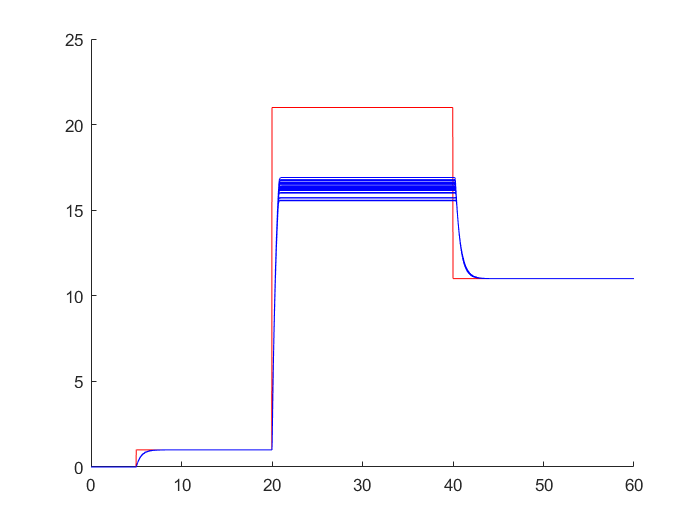

% Discrete simulation

figure; hold on;
for j=1:length(msys)

    output = sim('sim_disc');

    if j == 1
        plot(output.yout{2}.Values.Time, output.yout{2}.Values.Data, "r-")
    end

   plot(output.yout{1}.Values.Time, output.yout{1}.Values.Data, "b-")
end